## Hopf bifurcation of Schnakenberger system

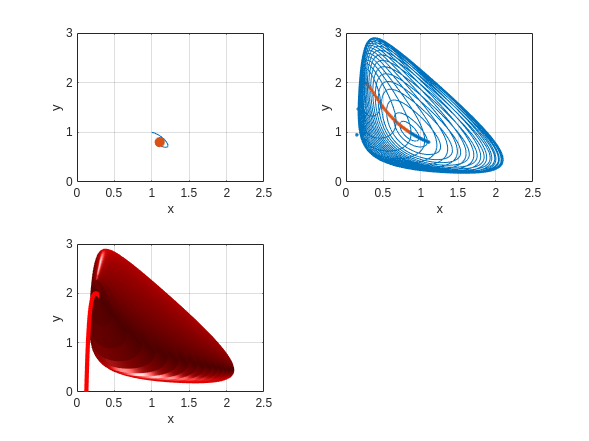

syms a mu x y real

assumeAlso(a > 0)
assumeAlso(mu > 0)
assumeAlso(mu < 1)

f_sym = [
    a - x + x^2*y
    mu - x^2*y
    ];

xy = [x;y];

sol = solve(f_sym,xy);

P_sym = [
    sol.x
    sol.y
    ];

Ap_sym = subs(jacobian(f_sym,xy),xy,P_sym);

D_sym = simplify(det(Ap_sym));
Tr_sym = simplify(trace(Ap_sym));

num_sym = simplify(numden(Tr_sym));

a = 1/8;

r = roots(sym2poly(subs(num_sym)));
r(r < 0) = [];
r1 = min(r);
r2 = max(r);
clear r

Step = 0.02;
mu_vals = sort([ (Step:Step:1-Step) r1 r2 ]);

mu_resulting_LC = mu_vals( r1 <= mu_vals & mu_vals <= r2 );
N = numel(mu_resulting_LC);

radian = -pi:0.005:pi;
M = numel(radian);

X = zeros(M,N);
Y = zeros(M,N);
MU = zeros(M,N);

f_fh = matlabFunction(subs(f_sym),'Vars',{xy,mu});
P_fh = matlabFunction(subs(P_sym),'Vars',{mu});
Ap_fh = matlabFunction(subs(Ap_sym),'Vars',{mu});
D_fh = matlabFunction(subs(D_sym),'Vars',{mu});
Tr_fh = matlabFunction(subs(Tr_sym),'Vars',{mu});

XLim = [0 2.5];
YLim = [0 3];
MuLim = [0 1];

fig = figure(312);
Tl = tiledlayout(2,2);
Ax1 = nexttile; hold on; grid on; box on;
xlim(XLim); 
ylim(YLim);
xlabel('x')
ylabel('y')
Pl = plot(0,0);
Pl_LC = plot(0,0,'LineWidth',2);

Ax2 = nexttile; hold on; grid on; box on;
view([0 0])
xlim(XLim); 
zlim(YLim);
ylim(MuLim);
xlabel('x')
ylabel('mu')
zlabel('y')

Color_1 = [0 0.4470 0.7410];
Color_2 = [0.8500 0.3250 0.0980];
Color_3 = [0.9290 0.6940 0.1250];
Color_4 = [0.4940 0.1840 0.5560];
Color_5 = [0.4660 0.6740 0.1880];
Color_6 = [0.3010 0.7450 0.9330];
Color_7 = [0.6350 0.0780 0.1840];

% Simulation time in seconds
Simulation_time = 10;
Step_time = Simulation_time / numel(mu_vals);
tic

T = 1000;
x0 = [1;1];
Idx_mesh = 1;
Eigs = zeros(2,numel(mu_vals));
for i = 1:numel(mu_vals)
    mu = mu_vals(i);

    [t_sol,x_sol] = ode45(@(~,x) f_fh(x,mu),[0 T],x0);

    % Update trajectory in Ax1
    Pl.XData = x_sol(:,1);
    Pl.YData = x_sol(:,2);

    P = P_fh(mu);
    A = Ap_fh(mu);
    Eigs(:,i) = eig(A);

    if r1 <= mu && mu <= r2
        % find period
        [pks,locs] = findpeaks(x_sol(:,1));
        T_period  = mean(diff(t_sol(locs)));

        % Get only the last 10 periods
        [~,Idx_Tp2] = min(abs(t_sol - (T - 10*T_period)));

        t_sol = t_sol(Idx_Tp2:end);
        x_sol = x_sol(Idx_Tp2:end,:);

        x_centered = x_sol - P';
        theta = atan2(x_centered(:,2),x_centered(:,1));
        [~,Idx_theta0] = min(theta);

        x0_in_LC = x_sol(Idx_theta0,:);

        % smallest step size
        dt = min( min(diff(t_sol)) , 0.05 );

        term_event = @(t,x) hp_ode_terminal_event_ball(t,x,x0_in_LC,0.01,"Direction",-1);
        opts = odeset('Events',term_event,'MaxStep',dt);
        [t_sol,x_sol] = ode45(@(~,x) f_fh(x,mu),[0 T_period],x0_in_LC,opts);        

        % Center limit cycle such that the origin is in its focus
        x_centered = x_sol - P';
        
        r = vecnorm(x_centered,2,2);
        theta = atan2(x_centered(:,2),x_centered(:,1));

        [theta,Idx] = sort(theta);
        r = r(Idx);

        x_sol = [ r.*cos(theta) , r.*sin(theta) ] + P';

        plot3(x_sol(:,1),x_sol(:,1)*0+mu,x_sol(:,2),'Color',Color_1);
        Pl_LC.XData = x_sol(:,1);
        Pl_LC.YData = x_sol(:,2);
        Pl_LC.Marker = 'none';
        drawnow

        plot3(P(1),mu,P(2),'.','Color',Color_2);
        

        x_sol = interp1([ theta ; theta(1) + 2*pi ],[x_sol ; x_sol(end,:)],radian);
        X(:,Idx_mesh) = x_sol(:,1); 
        Y(:,Idx_mesh) = x_sol(:,2); 
        MU(:,Idx_mesh) = mu;
        Idx_mesh = Idx_mesh + 1;
    else
        plot3(P(1),mu,P(2),'.','Color',Color_1);
        Pl_LC.XData = P(1);
        Pl_LC.YData = P(2);
        Pl_LC.Marker = '.';
        Pl_LC.MarkerSize = 25;
        drawnow
    end   


    Time_elapsed_in_loop = toc;
    pause(Step_time - Time_elapsed_in_loop)
    tic
end

Ax3 = nexttile; hold on; grid on; box on;
Sf = surf(X,MU,Y,'FaceColor','r','FaceAlpha',1,'EdgeColor','none');
Lght1 = light(Ax3,'Position',[0 0 1]);
Lght2 = light(Ax3,'Position',[0 0 -1]);

mu_vals_dense = 0:0.001:1;
P_vals = P_fh(mu_vals_dense);
plot3(P_vals(1,:),mu_vals_dense,P_vals(2,:),'Color','r','LineWidth',3)

xlim(XLim); 
zlim(YLim);
ylim(MuLim);
xlabel('x')
ylabel('mu')
zlabel('y')

Link1 = linkprop([Ax2,Ax3],'View');

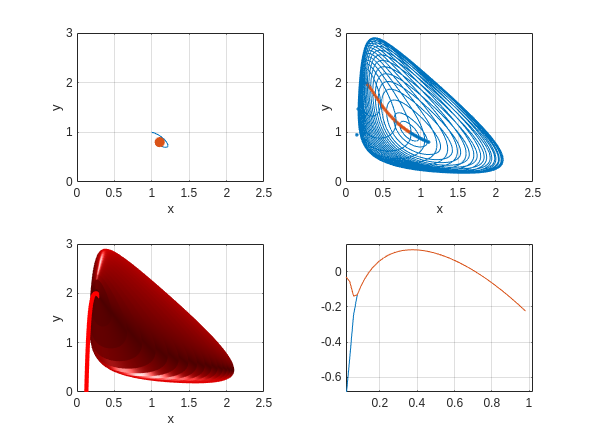

Ax4 = nexttile; hold on; grid on; box on;
plot3(mu_vals',real(Eigs'),imag(Eigs'))
xlabel('mu')
ylabel('Re(lambda)')
zlabel('Im(lambda)')